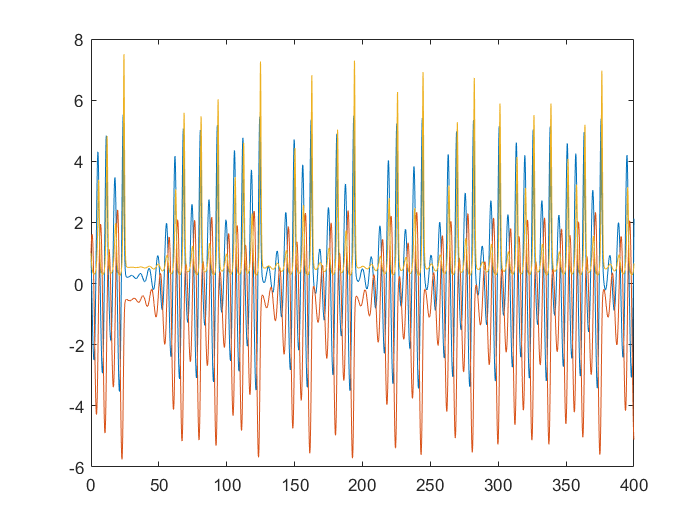

a = 0.432;
b = 2;
c = 4;
f = @(t, y) [-y(2) - y(3); y(1) + a*y(2); b + y(3)*(y(1) - c)];
[t2, y2] = ode45(f, [0, 400], [1; 1; 1]);
plot(t2, y2)

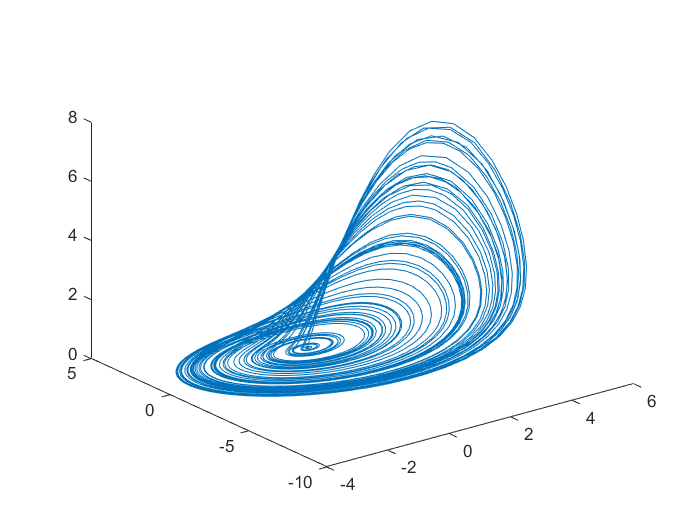

plot3(y2(:,1), y2(:,2), y2(:,3))

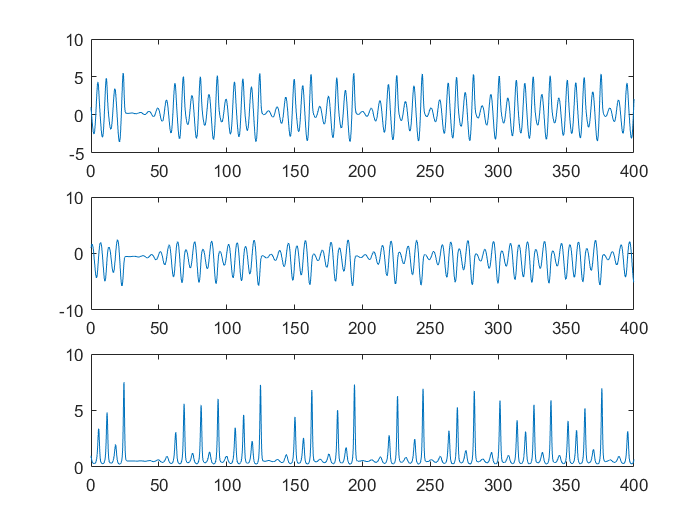

figure
subplot(3, 1, 1)
plot(t2, y2(:,1))
subplot(3, 1, 2)
plot(t2, y2(:,2))
subplot(3, 1, 3)
plot(t2, y2(:,3))